# Experiment 2: Using imagePretrainedNetwork (ResNet50) on Whole Image

## Clean environment

close all;
clear variables;
clc;
rng(42);

## Set folder path

folder = "C:\Users\u3253992\workspace\computer-vision\assignment_1\u3253992_assignment_1\data\CUB_200_2011_Subset20classes\";

## Load dataset

[trainingImageNames, validationImageNames, testImageNames, classNames, imageClassLabels] = loadDataset(folder);

No bounding Box


numClasses = height(classNames);

## Create datastores

disp('Training set class distribution:');

Training set class distribution:


trainingImageDS = createImageDatastore(trainingImageNames, folder);

    Label    Count
    _____    _____

     001      36  
     002      36  
     003      35  
     004      36  
     005      26  
     006      25  
     007      30  
     008      29  
     009      35  
     010      36  
     011      36  
     012      34  
     013      36  
     014      36  
     015      35  
     016      35  
     017      34  
     018      26  
     019      35  
     020      35  




disp('Validation set class distribution:');

Validation set class distribution:


validationImageDS = createImageDatastore(validationImageNames, folder);

    Label    Count
    _____    _____

     001       6  
     002      12  
     003      12  
     004      12  
     005       9  
     006       8  
     007      12  
     008      10  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      12  
     016      12  
     017      12  
     018      10  
     019      12  
     020      12  




disp('Test set class distribution:');

Test set class distribution:


testImageDS = createImageDatastore(testImageNames, folder);

    Label    Count
    _____    _____

     001      12  
     002      12  
     003      11  
     004      12  
     005       9  
     006       8  
     007      12  
     008       9  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      11  
     016      11  
     017      11  
     018       9  
     019      12  
     020      12  



## Load pretrained ResNet-50

net       = resnet50; % requires Deep Learning Toolbox Model for ResNet-50
inputSize = net.Layers(1).InputSize;

Unrecognized method, property, or field 'layers' for class 'DAGNetwork'.

## Resize image datastores and combine them with the labels

targetSize = inputSize(1:2);
trainCDS = resizeCombineDatastore(trainingImageDS, targetSize);
valCDS = resizeCombineDatastore(validationImageDS, targetSize);
testCDS = resizeCombineDatastore(testImageDS, targetSize);

## Show example images

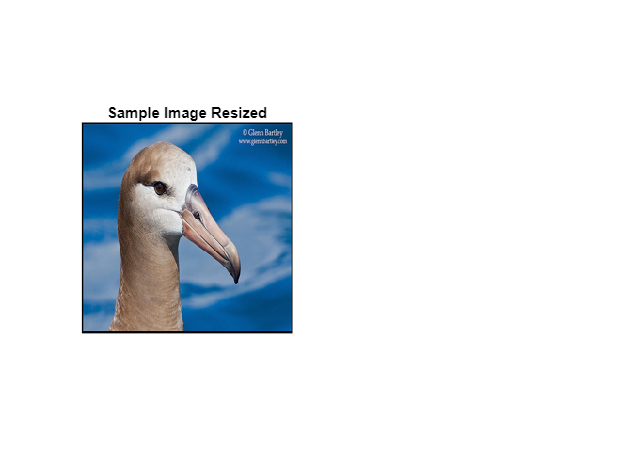

showImage(trainCDS)

## Enables GPU

[device, useGPU] = enableGPU();

✅ GPU found and ready:
  CUDADevice with properties:

                 Name: 'NVIDIA GeForce RTX 3070'
                Index: 1 (of 1)
    ComputeCapability: '8.6'
          DriverModel: 'WDDM'
          TotalMemory: 8589410304 (8.59 GB)
      AvailableMemory: 7443034112 (7.44 GB)
      DeviceAvailable: true
       DeviceSelected: true

  Show 

## Build the layer graph and swap out the last 3 layers

lgraph = layerGraph(net);

% 1) New fully‐connected layer (20 classes)
newFc = fullyConnectedLayer(numClasses, ...
    'Name','fc20', ...
    'WeightLearnRateFactor',10, ...
    'BiasLearnRateFactor',10);

% 2) New softmax
newSoftmax = softmaxLayer('Name','softmax20');

% 3) New classification output
newClassOutput = classificationLayer('Name','classoutput20');

% Replace them
lgraph = replaceLayer(lgraph, 'fc1000', newFc);
lgraph = replaceLayer(lgraph, 'fc1000_softmax', newSoftmax);
lgraph = replaceLayer(lgraph, 'ClassificationLayer_fc1000', newClassOutput);

## Training options

options = trainingOptions('adam', ...
    'MiniBatchSize',32, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',1e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',valCDS, ...
    'ValidationFrequency',floor(numel(trainingImageDS.Files)/32), ...
    'Verbose',true, ...
    'Plots','training-progress', ...
    'ExecutionEnvironment','gpu');

## Train the network

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |        9.38% |        9.91% |       3.2451 |       3.2372 |      1.0000e-04 |
|       1 |          20 |       00:00:13 |       75.00% |       72.07% |       0.6578 |       0.8540 |      1.0000e-04 |
|       2 |          40 |       00:00:22 |       93.75% |       78.83% |       0.3369 |       0.7062 |      1.0000e-04 |
|       3 |          50 |       00:00:26 |      100.00% |              |       0.0261 |              |      1.0000

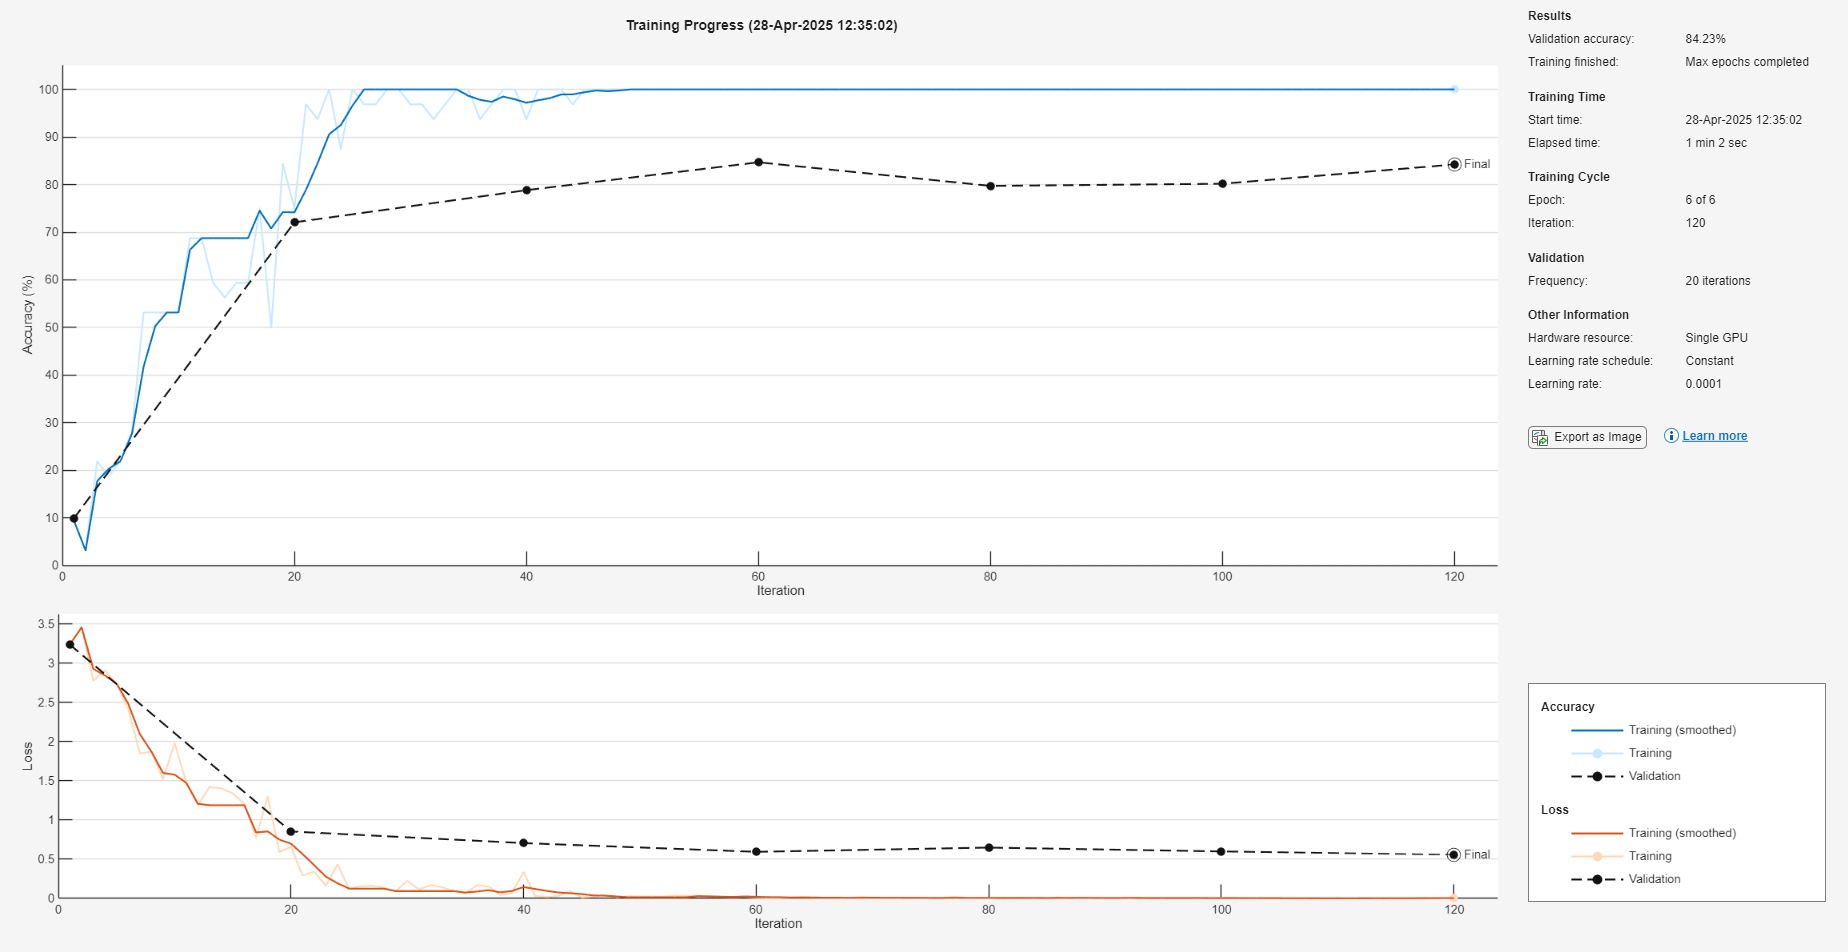

% trainedNet = trainnet(trainCDS, net, "crossentropy", options);
resnet20 = trainNetwork(trainCDS, lgraph, options);

## Evaluate the model

% scoresTest = minibatchpredict(trainedNet, testCDS)
% pred = scores2label(scoresTest,classNames.className);
% [~, yPred] = max(scoresTest, [], 2);
% % disp("Predictions");
% % disp(yPred);
% yTest = str2double(string(testImageDS.Labels))
% accuracy = sum(yPred == yTest) / numel(yTest);
% disp(accuracy)

[trainAcc, ~]   = evaluateClassifier(resnet20, trainCDS,   trainingImageDS.Labels,   true);
[valAcc,   ~]   = evaluateClassifier(resnet20, valCDS,     validationImageDS.Labels, true);
[testAcc, preds] = evaluateClassifier(resnet20, testCDS,   testImageDS.Labels,       true);

fprintf("Train Accuracy = %.1f%%\n", trainAcc*100);

Train Accuracy = 100.0%


fprintf("Val   Accuracy = %.1f%%\n", valAcc*100);

Val   Accuracy = 84.2%


fprintf("Test  Accuracy = %.1f%%\n", testAcc*100);

Test  Accuracy = 82.0%


## Plot confusion matrix

% plotConfusionMatrix(yTest, yPred, "Exp.2 ResNet-18 Overall Accuracy: " + string(round(accuracy*100, 1)) + "%");

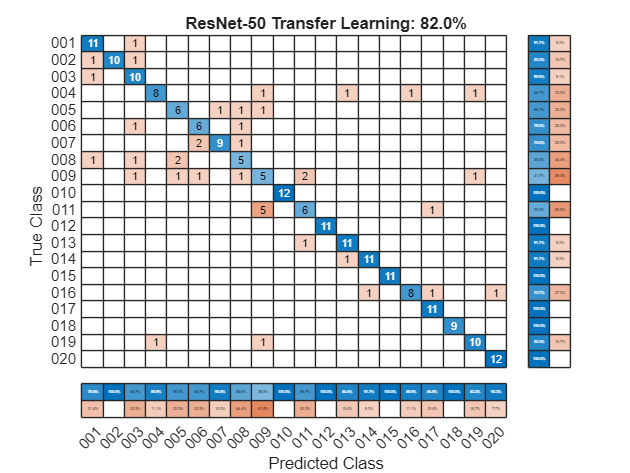

Classwise Recognition Rates:
   91.7000
   83.3000
   90.9000
   66.7000
   66.7000
   75.0000
   75.0000
   55.6000
   41.7000
  100.0000
   50.0000
  100.0000
   91.7000
   91.7000
  100.0000
   72.7000
  100.0000
  100.0000
   83.3000
  100.0000



plotConfusionMatrix(testImageDS.Labels, preds, ...
    sprintf("ResNet-50 Transfer Learning: %.1f%%", testAcc*100));